# **神经网络反向传播主程序**

%% Initialization
clear ; close all; clc

%% Setup the parameters you will use for this exercise
input_layer_size  = 400;  % 20x20 Input Images of Digits
hidden_layer_size = 25;   % 25 hidden units
num_labels = 10;          % 10 labels, from 1 to 10   
                          % (note that we have mapped "0" to label 10)

%% =========== Part 1: 加载和可视化数据 =============
%  We start the exercise by first loading and visualizing the dataset. 
%  You will be working with a dataset that contains handwritten digits.
% Load Training Data
load('ex1data.mat');
m = size(X, 1);

% Randomly select 100 data points to display
sel = randperm(size(X, 1));
sel = sel(1:100);
displayData(X(sel, :));
fprintf('数据已经加载完成并可视化。\n');

数据已经加载完成并可视化。



%% ================ Part 2: 加载参数 ================
% In this part of the exercise, we load some pre-initialized neural network parameters.
% Load the weights into variables Theta1 and Theta2
load('ex1weights.mat');

% Unroll parameters 
nn_params = [Theta1(:) ; Theta2(:)];
fprintf('参数已经加载完成。\n');

参数已经加载完成。



%% ================ Part 3: 计算成本（前向） ================
%  To the neural network, you should first start by implementing the feedforward part of the neural network that returns the cost only.
%  You should complete the code in nnCostFunction.m to return cost. 
%  After implementing the feedforward to compute the cost, 
%  you can verify that your implementation is correct by verifying that you get the same cost as us for the fixed debugging parameters.
%
%  We suggest implementing the feedforward cost *without* regularizationfirst so that it will be easier for you to debug.
%  Later, in part 4, you will get to implement the regularized cost.

% Weight regularization parameter (we set this to 0 here).
lambda = 0;
J = nnCostFunction(nn_params, input_layer_size, hidden_layer_size, ...
                   num_labels, X, y, lambda);

fprintf(['Cost at parameters (loaded from ex1weights): %f '...
         '\n(this value should be about 0.288401 )\n'], J);

Cost at parameters (loaded from ex1weights): 0.288401 
(this value should be about 0.288401 )


fprintf('\n第三部分完成\n');


第三部分完成



%% =============== Part 4: 实现正则化 ===============
%  Once your cost function implementation is correct, 
%  you should now continue to implement the regularization with the cost.

% Weight regularization parameter (we set this to 1 here).
lambda = 1;
J = nnCostFunction(nn_params, input_layer_size, hidden_layer_size, ...
                   num_labels, X, y, lambda);

fprintf(['Cost at parameters (loaded from ex1weights): %f '...
         '\n(this value should be about 0.408577)\n'], J);

Cost at parameters (loaded from ex1weights): 0.408577 
(this value should be about 0.408577)


fprintf('第四部分完成。\n');

第四部分完成。



%% ================ Part 5: 计算激活函数Sigmoid的梯度 ================
%  Before you start implementing the neural network, 
%  you will first implement the gradient for the sigmoid function. 
%  You should complete the code in the sigmoidGradient.m file.

g = sigmoidGradient([1 -0.5 0 0.5 1]);
fprintf('Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:\n  ');

Sigmoid gradient evaluated at [1 -0.5 0 0.5 1]:
  

fprintf('%f ', g);

0.196612 0.235004 0.250000 0.235004 0.196612 

fprintf('\n\n');

fprintf('第五部分完成。\n');

第五部分完成。



%% ================ Part 6: 初始化参数 ================
%   In this part of the exercise,
%   you will be starting to implment a two layer neural network that classifies digits.
%   You will start byimplementing a function to initialize the weights of the neural network

%   (randInitializeWeights.m)
initial_Theta1 = randInitializeWeights(input_layer_size, hidden_layer_size);
initial_Theta2 = randInitializeWeights(hidden_layer_size, num_labels);

% Unroll parameters
initial_nn_params = [initial_Theta1(:) ; initial_Theta2(:)];
fprintf('第六部分完成。\n');

第六部分完成。



%% =============== Part 7: 实现反向传播 ===============
%  Once your cost matches up with ours, you should proceed to implement the backpropagation algorithm for the neural network. 
%  You should add to the code you've written in nnCostFunction.m to return the partial derivatives of the parameters.

%  Check gradients by running checkNNGradients
checkNNGradients;

If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.998611


fprintf('第七部分完成，但计算出的梯度偏大。\n');

第七部分完成，但计算出的梯度偏大。



%% =============== Part 8: 实现正则化 ===============
%  Once your backpropagation implementation is correct,
%   you should now continue to implement the regularization with the cost and gradient.

%  Check gradients by running checkNNGradients
lambda = 3;
checkNNGradients(lambda);

If your backpropagation implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 0.775247



% Also output the costFunction debugging values
debug_J  = nnCostFunction(nn_params, input_layer_size, ...
                          hidden_layer_size, num_labels, X, y, lambda);
fprintf(['\n\nCost at (fixed) debugging parameters (w/ lambda = 10): %f ' ...
         '\n(this value should be about 0.648928)\n\n'], debug_J);



Cost at (fixed) debugging parameters (w/ lambda = 10): 0.648928 
(this value should be about 0.648928)



fprintf('第八部分完成。\n');

第八部分完成。



%% =================== Part 9: 训练神经网络 ===================
%  You have now implemented all the code necessary to train a neural network.
%  To train your neural network, we will now use "fmincg", which is a function which works similarly to "fminunc". 
%  Recall that these advanced optimizers are able to train our cost functions efficiently as long as we provide them with the gradient computations.

%  After you have completed the assignment, change the MaxIter to a larger value to see how more training helps.
options = optimset('MaxIter', 50);

%  You should also try different values of lambda
lambda = 1;

% Create "short hand" for the cost function to be minimized
costFunction = @(p) nnCostFunction(p, ...
                                   input_layer_size, ...
                                   hidden_layer_size, ...
                                   num_labels, X, y, lambda);

% Now, costFunction is a function that takes in only one argument (the neural network parameters)
[nn_params, cost] = fmincg(costFunction, initial_nn_params, options);

Iteration     1 | Cost: 3.288905e+00
Iteration     2 | Cost: 3.240229e+00
Iteration     3 | Cost: 3.172234e+00
Iteration     4 | Cost: 2.393031e+00
Iteration     5 | Cost: 2.125873e+00
Iteration     6 | Cost: 1.820086e+00
Iteration     7 | Cost: 1.677618e+00
Iteration     8 | Cost: 1.567029e+00
Iteration     9 | Cost: 1.414253e+00
Iteration    10 | Cost: 1.305390e+00
Iteration    11 | Cost: 1.251578e+00
Iteration    12 | Cost: 1.179647e+00
Iteration    13 | Cost: 1.151016e+00
Iteration    14 | Cost: 1.111231e+00
Iteration    15 | Cost: 1.036880e+00
Iteration    16 | Cost: 9.706538e-01
Iteration    17 | Cost: 8.766579e-01
Iteration    18 | Cost: 8.386730e-01
Iteration    19 | Cost: 8.177410e-01
Iteration    20 | Cost: 7.937885e-01
Iteration    21 | Cost: 7.767789e-01
Iteration    22 | Cost: 7.679439e-01
Iteration    23 | Cost: 7.468016e-01
Iteration    24 | Cost: 7.247122e-01
Iteration    25 | Cost: 6.998733e-01
Iteration    26 | Cost: 6.766642e-01
Iteration    27 | Cost: 6.651048e-01
I


% Obtain Theta1 and Theta2 back from nn_params
Theta1 = reshape(nn_params(1:hidden_layer_size * (input_layer_size + 1)), ...
                 hidden_layer_size, (input_layer_size + 1));
Theta2 = reshape(nn_params((1 + (hidden_layer_size * (input_layer_size + 1))):end), ...
                 num_labels, (hidden_layer_size + 1));

fprintf('第九部分完成。\n');

第九部分完成。


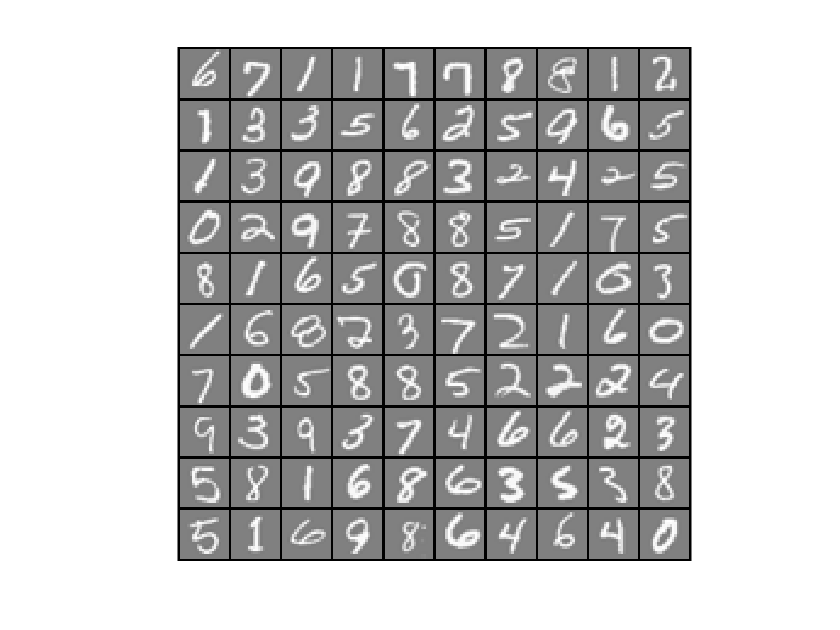

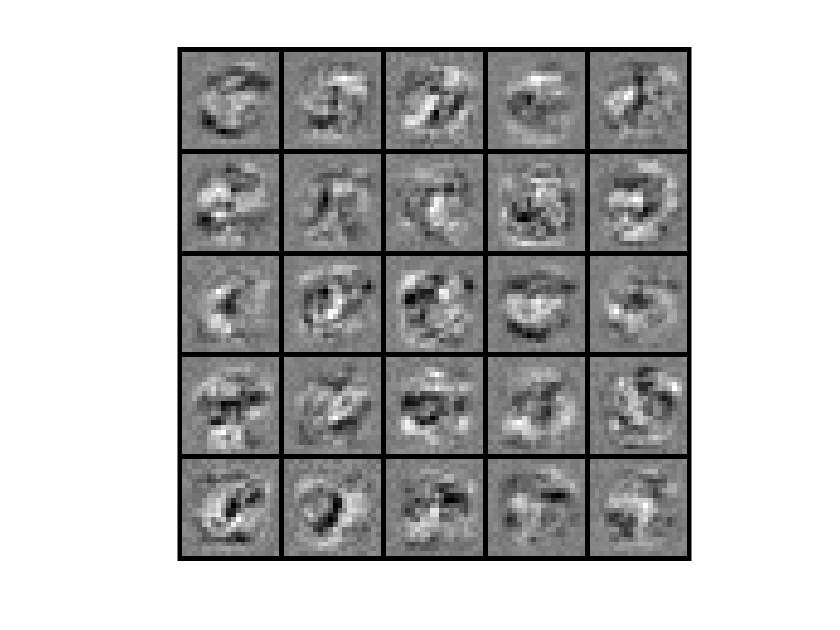


%% ================= Part 10: 可视化权重 =================
%  You can now "visualize" what the neural network is learning by displaying the hidden units  
%  to see what features they are capturing in the data.

displayData(Theta1(:, 2:end));

fprintf('第十部分完成。\n');

第十部分完成。



%% ================= Part 11: 实现预测 =================
%  After training the neural network, we would like to use it to predict the labels. 
%  You will now implement the "predict" function to use the neural network to predict the labels of the training set.
%  This lets you compute the training set accuracy.
pred = predict(Theta1, Theta2, X);
fprintf('\n Training Set Accuracy: %f\n', mean(double(pred == y)) * 100);


 Training Set Accuracy: 96.775000


fprintf('全部完成。\n');

全部完成。
